%% quadrupede_4pernas_fases.m
% Cinemática direta + inversa para 4 pernas (duas móveis em cada fase)
clear; close all; clc;


%% ------------------ TABELA DH (comum às pernas) ------------------
DH = [
    0,    0.035,  0.065,  -90;   % junta 1
    0,    0.000,  0.100,   180;  % junta 2
    90,   0.000,  0.165,   180;  % junta 3
];
n = size(DH,1);


%% ------------------ Bases das pernas (T0 -> primeiro referencial da perna) --
T0_to_J1 =  [1  0  0  0.07;
             0 -1  0  -0.083;
             0  0 -1   0;
             0  0  0   1];
T0_to_J1_final = aplicarRotacaoZAntes(45, T0_to_J1);


T0_to_J4 = [-1  0  0  -0.07;
             0  1  0   0.05;
             0  0 -1   0;
             0  0  0   1];
T0_to_J4_final = aplicarRotacaoZAntes(45, T0_to_J4);


T0_to_J7 = [1  0  0   0.07;
             0  -1  0  0.05;
             0  0 -1   0;
             0  0  0   1];
T0_to_J7_final = aplicarRotacaoZAntes(-45, T0_to_J7);


T0_to_J10 = [ -1  0  0  -0.07;
              0 1  0  -0.083;
              0  0 -1   0;
              0  0  0   1];
T0_to_J10_final = aplicarRotacaoZAntes(-45, T0_to_J10);


%% ------------------ Angulos iniciais (offsets relativos) ------------------
q0 = [0;0;0];   % configuração neutra de junta (offsets)


%% ------------------ Função auxiliar: montarPerna -------------------------
function [Ts,T_end,T0_adj] = montarPerna(T0_base,DH,q)
    nloc = size(DH,1);
    A = cell(nloc,1);
    Ts = zeros(4,4,nloc+1);
    Ts(:,:,1) = T0_base;
    Tprev = T0_base;
    for ii=1:nloc
        theta = DH(ii,1) + q(ii);
        d = DH(ii,2); a = DH(ii,3); alpha = DH(ii,4);
        A{ii} = dhA(theta,d,a,alpha);
        Tprev = Tprev * A{ii};
        Ts(:,:,ii+1) = Tprev;
    end
    T_end = Ts(:,:,end);
    % Ajuste z_end -> 0
    z_end = T_end(3,4);
    tol = 1e-6;
    T0_adj = T0_base;
    if abs(z_end) > tol
        T0_adj(3,4) = T0_adj(3,4) - z_end;
        Tprev = T0_adj; Ts(:,:,1) = T0_adj;
        for ii=1:nloc
            theta = DH(ii,1) + q(ii);
            d = DH(ii,2); a = DH(ii,3); alpha = DH(ii,4);
            A{ii} = dhA(theta,d,a,alpha);
            Tprev = Tprev * A{ii};
            Ts(:,:,ii+1) = Tprev;
        end
        T_end = Ts(:,:,end);
    end
end


%% ------------------ Monta as quatro pernas (pose inicial) -----------------
[Ts1,Te1,T0_to_J1_adj]   = montarPerna(T0_to_J1_final, DH, q0);
[Ts2,Te2,T0_to_J4_adj]   = montarPerna(T0_to_J4_final, DH, q0);
[Ts3,Te3,T0_to_J7_adj]   = montarPerna(T0_to_J7_final, DH, q0);
[Ts4,Te4,T0_to_J10_adj]  = montarPerna(T0_to_J10_final, DH, q0);


fprintf('E1: [x=%.3f, y=%.3f, z=%.3f]\n', Te1(1:3,4));

E1: [x=0.187, y=-0.200, z=0.000]


fprintf('E2: [x=%.3f, y=%.3f, z=%.3f]\n', Te2(1:3,4));

E2: [x=-0.187, y=0.167, z=0.000]


fprintf('E3: [x=%.3f, y=%.3f, z=%.3f]\n', Te3(1:3,4));

E3: [x=0.187, y=0.167, z=0.000]


fprintf('E4: [x=%.3f, y=%.3f, z=%.3f]\n', Te4(1:3,4));

E4: [x=-0.187, y=-0.200, z=0.000]




%% ------------------ Trajetórias / fases ---------------------------------
nPts = 30;
% perna1 (P1) e perna2 (P2) - arco
y_traj1 = linspace(Te1(2,4), Te1(2,4) - 0.05, nPts);
y_traj1_2 = linspace(Te1(2,4) - 0.05, Te1(2,4), nPts);
z_traj1 = 0.02 * sin(pi * (0:nPts-1)/(nPts-1));
z_traj1_2 = -0.02 * sin(pi * (0:nPts-1)/(nPts-1));
x_traj1 = ones(1,nPts) * Te1(1,4);
traj1 = [x_traj1; y_traj1; z_traj1];
traj1_2 = [x_traj1; y_traj1_2; z_traj1_2];

y_traj2 = linspace(Te2(2,4), Te2(2,4) - 0.05, nPts);
y_traj2_2 = linspace(Te2(2,4) - 0.05, Te2(2,4), nPts);
z_traj2 = 0.02 * sin(pi * (0:nPts-1)/(nPts-1));
z_traj2_2 = -0.02 * sin(pi * (0:nPts-1)/(nPts-1));
x_traj2 = ones(1,nPts) * Te2(1,4);
traj2 = [x_traj2; y_traj2; z_traj2];
traj2_2 = [x_traj2; y_traj2_2; z_traj2_2];

% perna3/perna4 movimento (passo 2)
y_traj3_move = linspace(Te3(2,4), Te3(2,4) - 0.05, nPts);
y_traj3_move_2 = linspace(Te3(2,4) - 0.05, Te3(2,4), nPts);
z_traj3_move = 0.02 * sin(pi * (0:nPts-1)/(nPts-1));
z_traj3_move_2 = -0.02 * sin(pi * (0:nPts-1)/(nPts-1));
x_traj3_move = ones(1,nPts) * Te3(1,4);
traj3_move = [x_traj3_move; y_traj3_move; z_traj3_move];
traj3_2_move = [x_traj3_move; y_traj3_move_2; z_traj3_move_2];

y_traj4_move = linspace(Te4(2,4), Te4(2,4) - 0.05, nPts);
y_traj4_move_2 = linspace(Te4(2,4) - 0.05, Te4(2,4), nPts);
z_traj4_move = 0.03 * sin(pi * (0:nPts-1)/(nPts-1));
z_traj4_move_2 = -0.03 * sin(pi * (0:nPts-1)/(nPts-1));
x_traj4_move = ones(1,nPts) * Te4(1,4);
traj4_move = [x_traj4_move; y_traj4_move; z_traj4_move];
traj4_2_move = [x_traj4_move; y_traj4_move_2; z_traj4_move_2];


% trajetórias inversas para retorno P1/P2 (passo 3)
traj1_rev = traj1(:, end:-1:1);
traj2_rev = traj2(:, end:-1:1);


% trajetórias inversas para retorno P3/P4 (passo 4)
traj3_rev = traj3_move(:, end:-1:1);
traj4_rev = traj4_move(:, end:-1:1);


%% estados atuais das juntas (em offset degrees), persistem entre fases
q_curr1 = q0; q_curr2 = q0; q_curr3 = q0; q_curr4 = q0;


%% históricos ampliados (4 fases)
nSteps = 4;
totalPts = nSteps * nPts;
q_history1 = zeros(nPts,3); % Armazenamento temporário por passo
q_history2 = zeros(nPts,3);
q_history3 = zeros(nPts,3);
q_history4 = zeros(nPts,3);
% O histórico 'q_history5' foi removido pois o robô só tem 4 pernas.
% O histórico 'q_history_all' será usado para a exportação final.
q_history_all = zeros(totalPts,12); % 4 pernas * 3 juntas = 12 colunas


%% ------------------ Históricos / Exportação por Passo -------------------
joint_names_all = {'P1_q1','P1_q2','P1_q3','P2_q1','P2_q2','P2_q3','P3_q1','P3_q2','P3_q3','P4_q1','P4_q2','P4_q3'};

% Imprime a pose inicial (Passo 0)
fprintf('\n=======================================================\n');

fprintf('  ** Angulos Iniciais (Offset Zero) - Passo 0 **\n');

  ** Angulos Iniciais (Offset Zero) - Passo 0 **


fprintf('=======================================================\n');


% Cria o vetor inicial com os novos offsets.
q_initial_all = [q_curr1', q_curr2', q_curr3', q_curr4'] + [90 100 120 110 100 85 70 60 90 90 60 75]; 

%Imprime a pose inicial
fprintf('{%.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f},\n', ...
    q_initial_all(1), q_initial_all(2), q_initial_all(3), ...
    q_initial_all(4), q_initial_all(5), q_initial_all(6), ...
    q_initial_all(7), q_initial_all(8), q_initial_all(9), ...
    q_initial_all(10), q_initial_all(11), q_initial_all(12));

{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},


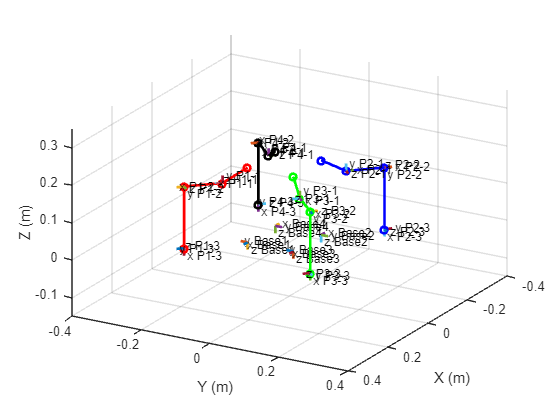



=== Passo 1: Pernas 1-2 Levantam/Avançam ===



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


--- Angulos do Passo 1: Pernas 1-2 Levantam/Avançam (4 pernas, 12 colunas, 30 pontos) ---


{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.4, 101.2, 120.8, 109.6, 101.2, 86.7, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.8, 102.5, 121.6, 109.1, 102.5, 88.3, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{91.2, 103.6, 122.3, 108.7, 103.6, 89.8, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{91.6, 104.8, 122.9, 108.3, 104.8, 91.3, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.0, 105.8, 123.5, 107.8, 105.9, 92.8, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.4, 106.8, 124.0, 107.3, 106.9, 94.1, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.8, 107.7, 124.4, 106.9, 107.8, 95.4, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.2, 108.5, 124.7, 106.4, 108.6, 96.5, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.6, 109.2, 124.9, 105.9, 109.4, 97.6, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.9, 109.8, 124.9, 105.4, 110.0, 98.5, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{94.3, 110.3, 124.9, 104.9, 110.5, 99.4, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{94.7, 110.6, 124.7, 104.4, 110.9, 100.1, 70.0, 60.0, 90.0, 90.0



=== Passo 2: Pernas 3-4 Levantam/Avançam ===



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


--- Angulos do Passo 2: Pernas 3-4 Levantam/Avançam (4 pernas, 12 colunas, 30 pontos) ---


{100.0, 97.4, 103.9, 94.7, 98.4, 94.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{99.7, 96.3, 103.3, 95.4, 97.2, 92.6, 70.4, 61.2, 91.7, 89.6, 61.9, 76.4},
{99.4, 95.3, 102.7, 96.0, 96.1, 91.1, 70.9, 62.5, 93.3, 89.2, 63.7, 77.8},
{99.2, 94.2, 102.1, 96.6, 95.0, 89.6, 71.3, 63.6, 94.8, 88.8, 65.5, 79.0},
{98.9, 93.2, 101.5, 97.2, 93.9, 88.2, 71.7, 64.8, 96.3, 88.4, 67.2, 80.2},
{98.6, 92.2, 100.9, 97.8, 92.9, 86.8, 72.2, 65.9, 97.8, 88.0, 68.8, 81.2},
{98.3, 91.3, 100.4, 98.4, 92.0, 85.5, 72.7, 66.9, 99.1, 87.6, 70.3, 82.2},
{98.0, 90.5, 100.0, 99.0, 91.2, 84.2, 73.1, 67.8, 100.4, 87.2, 71.7, 82.9},
{97.7, 89.7, 99.7, 99.6, 90.4, 83.0, 73.6, 68.6, 101.5, 86.8, 72.9, 83.6},
{97.3, 89.1, 99.4, 100.2, 89.7, 81.9, 74.1, 69.4, 102.6, 86.4, 74.0, 84.0},
{97.0, 88.6, 99.3, 100.7, 89.1, 80.9, 74.6, 70.0, 103.5, 86.1, 74.9, 84.4},
{96.7, 88.1, 99.3, 101.3, 88.7, 80.1, 75.1, 70.5, 104.4, 85.7, 75.6, 84.5},
{96.4, 87.9, 99.4, 101.8, 88.4, 79.3, 75.6, 70.9, 105.1, 85.3, 76.1, 84.5},
{96.0, 87.7, 99.7, 



=== Passo 3: Pernas 1-2 Retornam/Abaixam ===



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


--- Angulos do Passo 3: Pernas 1-2 Retornam/Abaixam (4 pernas, 12 colunas, 30 pontos) ---


{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 85.3, 58.4, 99.0, 80.0, 57.4, 58.9},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 84.6, 57.2, 97.6, 80.3, 55.7, 57.6},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 84.0, 56.1, 96.1, 80.6, 54.0, 56.3},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 83.4, 55.0, 94.6, 80.8, 52.3, 55.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 82.8, 53.9, 93.2, 81.1, 50.7, 53.8},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 82.2, 52.9, 91.8, 81.4, 49.1, 52.5},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 81.6, 52.0, 90.5, 81.7, 47.7, 51.4},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 81.0, 51.2, 89.2, 82.0, 46.3, 50.3},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 80.4, 50.4, 88.0, 82.3, 45.1, 49.4},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 79.8, 49.7, 86.9, 82.7, 44.0, 48.6},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 79.3, 49.1, 85.9, 83.0, 43.1, 48.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 78.7, 48.7, 85.1, 83.3, 42.4, 47.7},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 78.2, 48.4, 84.3, 83.6,



=== Passo 4: Pernas 3-4 Retornam/Abaixam ===



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>



Initial point is a local minimum.

Optimization completed because the size of the gradient at the initial point 
is less than the value of the optimality tolerance.

<stopping criteria details>


--- Angulos do Passo 4: Pernas 3-4 Retornam/Abaixam (4 pernas, 12 colunas, 30 pontos) ---


{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0,



%% Figura para animação conjunta
figure('Color','w'); hold on; grid on; axis equal;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
view(120,20);
%view(179.715, 0.486);
frame_scale = 0.02;
axis_lim = 0.40;
xlim([-axis_lim axis_lim]); ylim([-0.40 0.40]); zlim([-0.15 0.35]);


% % desenha trajetórias visuais
% plot3(traj1(1,:), traj1(2,:), traj1(3,:), 'r--', 'LineWidth',1.0);
% plot3(traj2(1,:), traj2(2,:), traj2(3,:), 'b--', 'LineWidth',1.0);
% plot3(traj3_move(1,:), traj3_move(2,:), traj3_move(3,:), 'g--', 'LineWidth',0.8);
% plot3(traj4_move(1,:), traj4_move(2,:), traj4_move(3,:), 'k--', 'LineWidth',0.8);


stepLabels = {'Passo 1: Pernas 1-2 Levantam/Avançam', 'Passo 2: Pernas 3-4 Levantam/Avançam', 'Passo 3: Pernas 1-2 Retornam/Abaixam', 'Passo 4: Pernas 3-4 Retornam/Abaixam'};


for step = 1:nSteps
    fprintf('\n\n=== %s ===\n', stepLabels{step});

    % Reseta históricos por passo
    q_history1 = zeros(nPts,3);
    q_history2 = zeros(nPts,3);
    q_history3 = zeros(nPts,3);
    q_history4 = zeros(nPts,3);

    for k = 1:nPts
        idx_global = (step-1)*nPts + k;


        switch step
            case 1 
                p_target1 = traj1(:,k);
                p_target2 = traj2(:,k);
                p_target3 = Te3(1:3,4); 
                p_target4 = Te4(1:3,4);


                move1 = true; move2 = true;
                move3 = false; move4 = false;


            case 2
                p_target1 = traj1_2(:,k);
                p_target2 = traj2_2(:,k);
                p_target3 = traj3_move(:,k);
                p_target4 = traj4_move(:,k);


                move1 = true; move2 = true;
                move3 = true; move4 = true;


            case 3  
                p_target1 = T_end1(1:3,4); 
                p_target2 = T_end2(1:3,4); 
                p_target3 = traj3_2_move(:,k); 
                p_target4 = traj4_2_move(:,k);


                move1 = false; move2 = false;
                move3 = true; move4 = true;


            % case 4  
            %     p_target1 = T_end1(1:3,4); 
            %     p_target2 = T_end2(1:3,4); 
            %     p_target3 = traj3_2_move(:,k); 
            %     p_target4 = traj4_2_move(:,k);
            % 
            % 
            %     move1 = false; move2 = false;
            %     move3 = true; move4 = true;
        end


       % --- Perna 1 ---
        if move1
            pos_err_fun1 = @(qvar) (forward_pos_position(qvar, DH, T0_to_J1_adj) - p_target1);
            % q_curr1 é usado como chute inicial (guess) e mantém o offset
            q_new1 = lsqnonlin(pos_err_fun1, q_curr1, [-70 -60 -30], [70 60 30]);
            q_curr1 = q_new1;
        end
        [T_end1, Ts1] = forward_kinematics(q_curr1, DH, T0_to_J1_adj);
        q_history1(k,:) = q_curr1' + [90 100 120];
        q_history_all(idx_global, 1:3) = q_history1(k,:);


        % --- Perna 2 ---
        if move2
            pos_err_fun2 = @(qvar) (forward_pos_position(qvar, DH, T0_to_J4_adj) - p_target2);
            q_new2 = lsqnonlin(pos_err_fun2, q_curr2, [-60 -60 -30], [60 60 30]);
            q_curr2 = q_new2;
        end
        [T_end2, Ts2] = forward_kinematics(q_curr2, DH, T0_to_J4_adj);
        q_history2(k,:) = q_curr2' + [110 100 85];
        q_history_all(idx_global, 4:6) = q_history2(k,:);


        % --- Perna 3 ---
        if move3
            pos_err_fun3 = @(qvar) (forward_pos_position(qvar, DH, T0_to_J7_adj) - p_target3);
            q_new3 = lsqnonlin(pos_err_fun3, q_curr3, [-50 -40 -30], [90 80 30]);
            q_curr3 = q_new3;
        end
        [T_end3, Ts3] = forward_kinematics(q_curr3, DH, T0_to_J7_adj);
        q_history3(k,:) = q_curr3' + [70 60 90];
        q_history_all(idx_global, 7:9) = q_history3(k,:);


        % --- Perna 4 ---
        if move4
            pos_err_fun4 = @(qvar) (forward_pos_position(qvar, DH, T0_to_J10_adj) - p_target4);
            q_new4 = lsqnonlin(pos_err_fun4, q_curr4, [-70 -40 -30], [70 80 30]);
            q_curr4 = q_new4;
        end
        [T_end4, Ts4] = forward_kinematics(q_curr4, DH, T0_to_J10_adj);
        q_history4(k,:) = q_curr4' + [90 60 75];
        q_history_all(idx_global, 10:12) = q_history4(k,:);


        % --- Atualiza desenho ---
        delete(findobj(gca,'Tag','link'));
        delete(findobj(gca,'Tag','frame'));


        plotFrame(T0_to_J1, frame_scale, 'Base1','frame');
        plotFrame(T0_to_J4, frame_scale, 'Base2','frame');
        plotFrame(T0_to_J7, frame_scale, 'Base3','frame');
        plotFrame(T0_to_J10, frame_scale, 'Base4','frame');


        % perna1
        for i = 1:size(DH,1)
            plotFrame(Ts1(:,:,i+1), frame_scale, sprintf('P1-%d',i),'frame');
            p0 = Ts1(1:3,4,i); p1 = Ts1(1:3,4,i+1);
            plot3([p0(1) p1(1)], [p0(2) p1(2)], [p0(3) p1(3)], '-or', 'LineWidth', 2, 'MarkerSize',5,'Tag','link');
        end
        plot3(T_end1(1,4), T_end1(2,4), T_end1(3,4), 'ro','MarkerSize',6,'Tag','link');


        % perna2
        for i = 1:size(DH,1)
            plotFrame(Ts2(:,:,i+1), frame_scale, sprintf('P2-%d',i),'frame');
            p0 = Ts2(1:3,4,i); p1 = Ts2(1:3,4,i+1);
            plot3([p0(1) p1(1)], [p0(2) p1(2)], [p0(3) p1(3)], '-ob', 'LineWidth', 2, 'MarkerSize',5,'Tag','link');
        end
        plot3(T_end2(1,4), T_end2(2,4), T_end2(3,4), 'bo','MarkerSize',6,'Tag','link');


        % perna3
        for i = 1:size(DH,1)
            plotFrame(Ts3(:,:,i+1), frame_scale, sprintf('P3-%d',i),'frame');
            p0 = Ts3(1:3,4,i); p1 = Ts3(1:3,4,i+1);
            plot3([p0(1) p1(1)], [p0(2) p1(2)], [p0(3) p1(3)], '-og', 'LineWidth', 2, 'MarkerSize',5,'Tag','link');
        end
        plot3(T_end3(1,4), T_end3(2,4), T_end3(3,4), 'go','MarkerSize',6,'Tag','link');


        % perna4
        for i = 1:size(DH,1)
            plotFrame(Ts4(:,:,i+1), frame_scale, sprintf('P4-%d',i),'frame');
            p0 = Ts4(1:3,4,i); p1 = Ts4(1:3,4,i+1);
            plot3([p0(1) p1(1)], [p0(2) p1(2)], [p0(3) p1(3)], '-ok', 'LineWidth', 2, 'MarkerSize',5,'Tag','link');
        end
        plot3(T_end4(1,4), T_end4(2,4), T_end4(3,4), 'ko','MarkerSize',6,'Tag','link');


        drawnow;
        pause(0.05);
    end

    % --- IMPRESSÃO POR PASSO ---
    fprintf('--- Angulos do %s (4 pernas, 12 colunas, %d pontos) ---\n', stepLabels{step}, nPts);
    % Combina os 30 pontos de q_history1 a q_history4 em uma única matriz para impressão
    q_step_history = [q_history1, q_history2, q_history3, q_history4];

    for k_step = 1:nPts
        q_line = q_step_history(k_step,:);
        fprintf('{%.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f},\n', ...
            q_line(1), q_line(2), q_line(3), ...
            q_line(4), q_line(5), q_line(6), ...
            q_line(7), q_line(8), q_line(9), ...
            q_line(10), q_line(11), q_line(12));
    end
end



% A matriz q_history_all já foi preenchida dentro do loop, só precisamos exportar.
q_table_all = array2table(q_history_all,'VariableNames',joint_names_all);


fprintf('\n=======================================================\n');

disp('--- Array final formatado para ESP32 (Todos os passos) ---')

--- Array final formatado para ESP32 (Todos os passos) ---


fprintf('=======================================================\n');

for k = 1:height(q_table_all)
    fprintf('{%.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f, %.1f},\n', ...
        q_table_all{k,1}, q_table_all{k,2}, q_table_all{k,3}, ...
        q_table_all{k,4}, q_table_all{k,5}, q_table_all{k,6}, ...
        q_table_all{k,7}, q_table_all{k,8}, q_table_all{k,9}, ...
        q_table_all{k,10}, q_table_all{k,11}, q_table_all{k,12});
end

{90.0, 100.0, 120.0, 110.0, 100.0, 85.0, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.4, 101.2, 120.8, 109.6, 101.2, 86.7, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{90.8, 102.5, 121.6, 109.1, 102.5, 88.3, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{91.2, 103.6, 122.3, 108.7, 103.6, 89.8, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{91.6, 104.8, 122.9, 108.3, 104.8, 91.3, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.0, 105.8, 123.5, 107.8, 105.9, 92.8, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.4, 106.8, 124.0, 107.3, 106.9, 94.1, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{92.8, 107.7, 124.4, 106.9, 107.8, 95.4, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.2, 108.5, 124.7, 106.4, 108.6, 96.5, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.6, 109.2, 124.9, 105.9, 109.4, 97.6, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{93.9, 109.8, 124.9, 105.4, 110.0, 98.5, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{94.3, 110.3, 124.9, 104.9, 110.5, 99.4, 70.0, 60.0, 90.0, 90.0, 60.0, 75.0},
{94.7, 110.6, 124.7, 104.4, 110.9, 100.1, 70.0, 60.0, 90.0, 90.0

fprintf('... total de %d linhas ...\n', totalPts);

... total de 120 linhas ...




%% ----------------- Funções locais usadas acima -------------------------
% aplica rotação antes da transformação (rotar referencial do corpo)
function T_final = aplicarRotacaoZAntes(angulo_graus, T_original)
    theta = angulo_graus;
    Rz_3x3 = [cosd(theta) -sind(theta) 0;
              sind(theta)  cosd(theta) 0;
              0           0          1];
    T_RotZ = [Rz_3x3, zeros(3, 1); 
              0 0 0, 1];
    T_final = T_original * T_RotZ;
end


function p = forward_pos_position(qvar, DH, T0_base)
    T = forward_kinematics(qvar, DH, T0_base);
    p = T(1:3,4);
end


function [T_end, Ts] = forward_kinematics(qvec, DH, T0_base)
    nloc = size(DH,1);
    Ts = zeros(4,4,nloc+1);
    Ts(:,:,1) = T0_base;
    Tprev = T0_base;
    for jj=1:nloc
        theta_off = DH(jj,1);
        d = DH(jj,2); a = DH(jj,3); alpha = DH(jj,4);
        theta = theta_off + qvec(jj);
        Ai = dhA(theta, d, a, alpha);
        Tprev = Tprev * Ai;
        Ts(:,:,jj+1) = Tprev;
    end
    T_end = Ts(:,:,end);
end


function A = dhA(theta_deg, d, a, alpha_deg)
    th = deg2rad(theta_deg); al = deg2rad(alpha_deg);
    A = [ cos(th),         -sin(th)*cos(al),    sin(th)*sin(al),    a*cos(th);
          sin(th),          cos(th)*cos(al),   -cos(th)*sin(al),    a*sin(th);
          0,                sin(al),            cos(al),            d;
          0,                0,                  0,                  1];
end


function plotFrame(T, s, name, tag)
    if nargin < 2, s = 0.03; end
    if nargin < 4, tag = 'frame'; end
    o = T(1:3,4);
    x = o + s * T(1:3,1);
    y = o + s * T(1:3,2);
    z = o + s * T(1:3,3);
    plot3([o(1) x(1)], [o(2) x(2)], [o(3) x(3)], '-', 'LineWidth', 2,'Tag',tag);
    plot3([o(1) y(1)], [o(2) y(2)], [o(3) y(3)], '-', 'LineWidth', 2,'Tag',tag);
    plot3([o(1) z(1)], [o(2) z(2)], [o(3) z(3)], '-', 'LineWidth', 2,'Tag',tag);
    text(x(1), x(2), x(3), [' x ' name], 'FontSize', 9,'Tag',tag);
    text(y(1), y(2), y(3), [' y ' name], 'FontSize', 9,'Tag',tag);
    text(z(1), z(2), z(3), [' z ' name], 'FontSize', 9,'Tag',tag);
end
